# Practica 1: Señales de Tiempo Discreto

- Utilice Matlab para generar y graficar las siguientes secuencias:

a) $x_1 \left(n\right)=3\delta \left(n-3\right)\;\;\;\;\;\;\;\;\;0\le n\le 10$

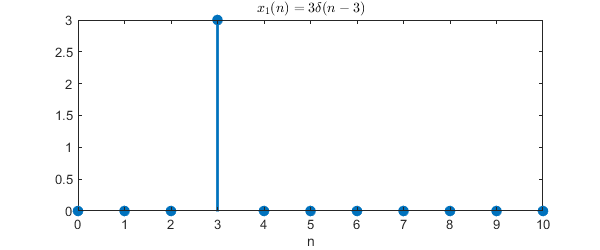

impulso = @(n) n==0;
n=0:10;
figure('Position',[500 400 600 250])
stem(n,3*impulso(n-3),'filled','LineWidth',2)
syms n
title('$ x_1(n)=3\delta(n-3) $','Interpreter','latex')
xlabel('n')

b) $x_2 \left(n\right)=5\delta \left(n-5\right)\;\;\;\;\;\;\;\;\;0\le n\le 10$

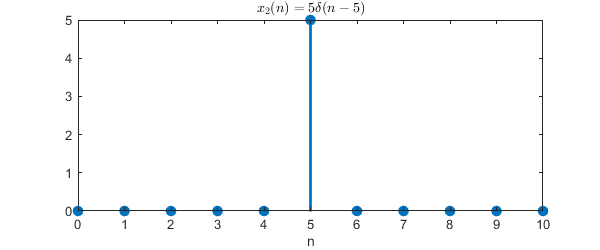

impulso = @(n) n==0;
n=0:10;
stem(n,5*impulso(n-5),'filled','LineWidth',2)
syms n
title('$ x_2(n)=5\delta(n-5) $','Interpreter','latex')
xlabel('n')

           2. Utilice Matlab para generar y graficar las siguientes secuencias:

a) $x_1 \left(n\right)=\sum_{k=-\infty }^{\infty } \delta \left(n-5k\right)\;\;\;\;\;\;\;\;\;-10\le n\le 10$

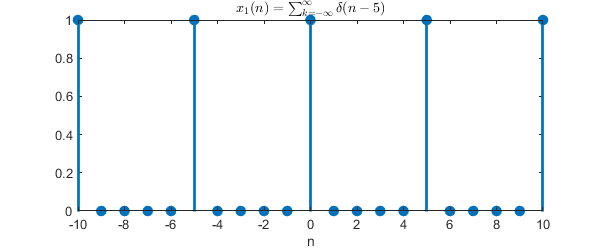

trenImp = @(n,N) mod(n,N)==0;
n=-10:10;
stem(n,trenImp(n,5),'filled','LineWidth',2)
syms n
title('$ x_1(n)=\sum_{k=-\infty}^{\infty}\delta(n-5)$','Interpreter','latex')
xlabel('n')

b) $x_2 \left(n\right)=\sum_{k=-\infty }^{\infty } \delta \left(n-4k\right)\;\;\;\;\;\;\;\;\;-10\le n\le 10$

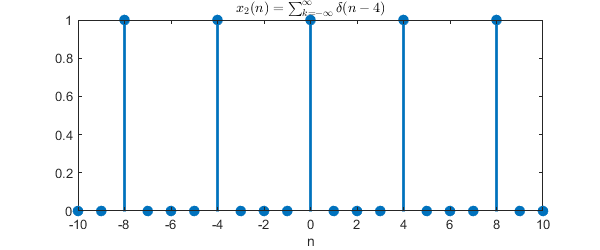

trenImp = @(n,N) mod(n,N)==0;
n=-10:10;
stem(n,trenImp(n,4),'filled','LineWidth',2)
title('$ x_2(n)=\sum_{k=-\infty}^{\infty}\delta(n-4)$','Interpreter','latex')
xlabel('n')

            3. Utilice Matlab para generar y graficar las siguientes secuencias

a) $x_1 \left(n\right)=3u\left(n-3\right)\;\;\;\;\;\;\;\;\;0\le n\le 10$

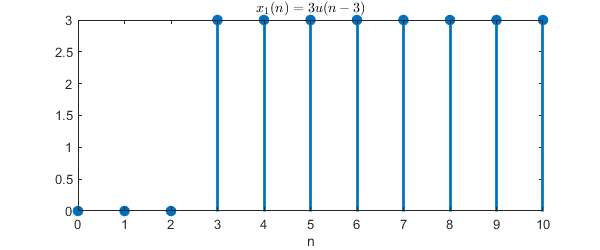

escalon = @(n) n>=0;
n=0:10;
stem(n,3*escalon(n-3),"filled","LineWidth",2)
title('$ x_1(n)=3u(n-3)$','Interpreter','latex')
xlabel('n')

b) $x_2 \left(n\right)=5u\left(n-5\right)\;\;\;\;\;\;\;\;\;0\le n\le 10$

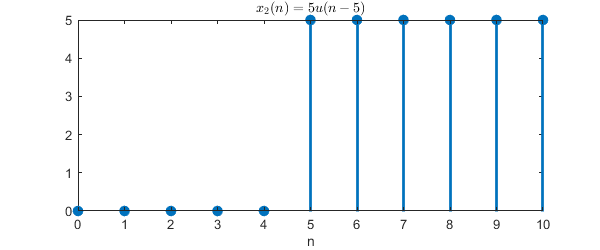

escalon = @(n) n>=0;
n=0:10;
stem(n,5*escalon(n-5),"filled","LineWidth",2)
title('$ x_2(n)=5u(n-5)$','Interpreter','latex')
xlabel('n')

            4. Utilice Matlab para generar y graficar las siguientes secuencias

a) $x_1 \left(n\right)={\left(\ldotp 5\right)}^n \;\;\;\;\;\;\;\;\;-2\le n\le 5$

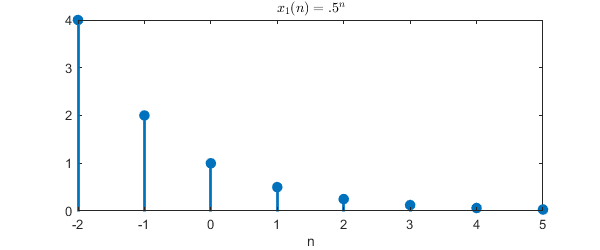

exponencial = @(a,n) (a.^n);
n=-2:5;
stem(n,exponencial(.5,n),"filled","LineWidth",2)
title('$ x_1(n)=.5^{n}$','Interpreter','latex')
xlabel('n')

b) $x_2 \left(n\right)={\left(-\ldotp 5\right)}^n \;\;\;\;\;\;\;\;\;-2\le n\le 5$

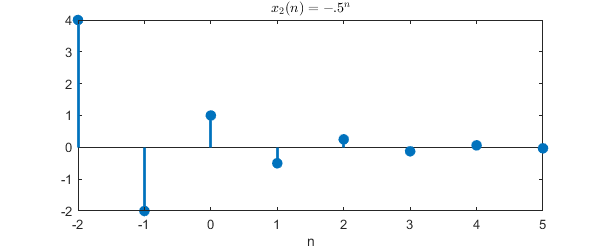

exponencial = @(a,n) (a.^n);
n=-2:5;
stem(n,exponencial(-.5,n),"filled","LineWidth",2)
title('$ x_2(n)=-.5^{n}$','Interpreter','latex')
xlabel('n')

            5. Utilice Matlab para generar y graficar las siguientes secuencias

a) $x_1 \left(n\right)=\sin \left(\frac{n\pi }{5}\right)\;\;\;\;\;\;\;\;\;-10\le n\le 10$

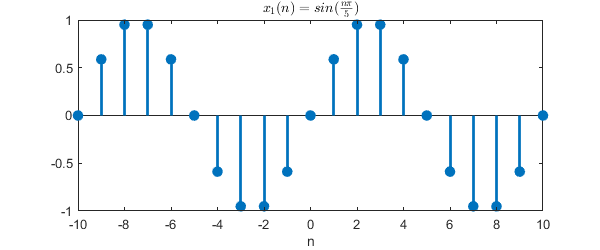

seno = @(wo,n) sin(wo*n);
n=-10:10;
stem(n,seno(pi/5,n),"filled","LineWidth",2)
title('$ x_1(n)= sin(\frac{n\pi}{5})$','Interpreter','latex')
xlabel('n')

b) $x_2 \left(n\right)=\sin \left(\frac{2n\pi }{5}\right)\;\;\;\;\;\;\;\;\;-10\le n\le 10$

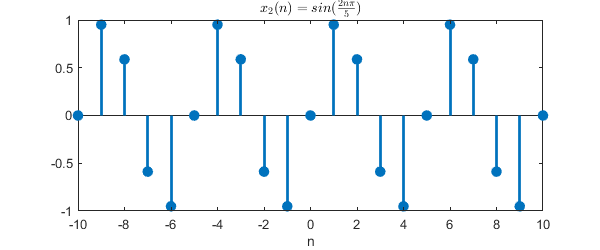

seno = @(wo,n) sin(wo*n);
n=-10:10;
stem(n,seno(2*pi/5,n),"filled","LineWidth",2)
title('$ x_2(n)= sin(\frac{2n\pi}{5})$','Interpreter','latex')
xlabel('n')

            6. Utilice Matlab para generar y graficar las siguientes secuencias.

a) $x_1 \left(n\right)=e^{\frac{-\textrm{jn}\pi }{5}} \;\;\;\;\;\;\;\;\;-10\le n\le 10$

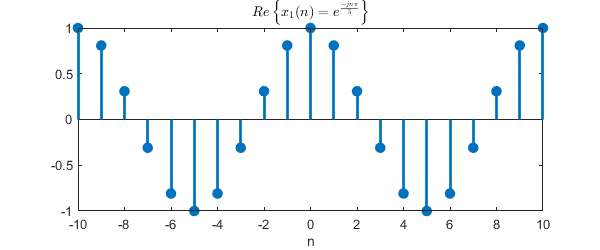

expCompleja = @(wo,n) exp(1i*wo*n);
n=-10:10;
stem(n,real(expCompleja(pi/5,n)),"filled","LineWidth",2)
title('$ Re \left\lbrace x_1(n)= e^{\frac{-jn\pi}{5}} \right\rbrace $','Interpreter','latex')
xlabel('n')

b) $x_2 \left(n\right)=e^{\frac{-\textrm{jn}\pi }{5}} \;\;\;\;\;\;\;\;\;-10\le n\le 10$

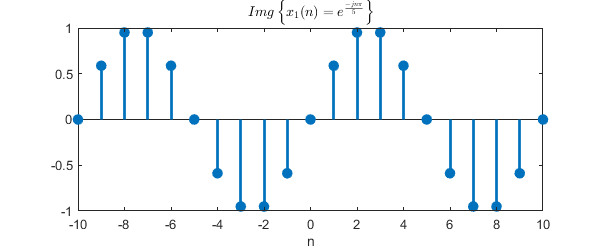

expCompleja = @(wo,n) exp(1i*wo*n);
n=-10:10;
stem(n,imag(expCompleja(pi/5,n)),"filled","LineWidth",2)
title('$ Img \left\lbrace x_1(n)= e^{\frac{-jn\pi}{5}} \right\rbrace $','Interpreter','latex')
xlabel('n')

                                Anexo: Codigo de Matlab

clear all;

clc

close all;

impulso = @(n) n==0;

escalon = @(n) n>=0;

trenImp = @(n,N) mod(n,N)==0;

exponencial = @(a,n) (a.^n);

seno = @(wo,n) sin(wo*n);

expCompleja = @(wo,n) exp(1i*wo*n);

n=0:10;

figure(1)

subplot(211)

stem(n,3*impulso(n-3),'filled','LineWidth',2)

title('x_1(n)')

xlabel('n')

subplot(212)

stem(n,5*impulso(n-5),'filled','LineWidth',2)

title('x_1(n)')

xlabel('n')

n=-10:10;

figure(2)

subplot(211)

stem(n,trenImp(n,5),'filled','LineWidth',2)

title('x_1(n)')

xlabel('n')

subplot(212)

stem(n,trenImp(n,4),'filled','LineWidth',2)

title('x_2(n)')

xlabel('n')

n=0:10;

figure(3)

subplot(211)

stem(n,3*escalon(n-3),'filled','LineWidth',2)

title('x_1(n)')

xlabel('n')

subplot(212)

stem(n,5*escalon(n-5),'filled','LineWidth',2)

title('x_2(n)')

xlabel('n')

n=-2:5;

figure(4)

subplot(211)

stem(n,exponencial(.5,n),'filled','LineWidth',2)

title('x_1(n)')

xlabel('n')

subplot(212)

stem(n,exponencial(-.5,n),'filled','LineWidth',2)

title('x_2(n)')

xlabel('n')

n=-10:10;

figure(5)

subplot(211)

stem(n,seno(pi/5,n),'filled','LineWidth',2)

title('x_1(n)')

xlabel('n')

subplot(212)

stem(n,seno(2*pi/5,n),'filled','LineWidth',2)

title('x_2(n)')

xlabel('n')

n=-10:10;

figure(6)

subplot(211)

stem(n,real(expCompleja(pi/5,n)),'filled','LineWidth',2)

title('x_1(n)')

xlabel('n')

subplot(212)

stem(n,imag(expCompleja(pi/5,n)),'filled','LineWidth',2)

title('x_2(n)')

xlabel('n')